clear; clc;
imu = serialport("COM12", 115200);

readline(imu)

ans =     "0.7430, -0.1399, -0.6543, 0.0155
     "


tic;
stopTimer = 1;

i=1;
while toc<stopTimer
    data = readline(imu);
    data = str2double(strsplit(data, ','));
    accel{i} = data(2:4);
    gyro{i} = data(5:7);
    mag{i} = data(8:end);
    i=i+1;
end

다음 사용 중 오류가 발생함: strsplit
첫 번째 입력값은 문자형 벡터이거나 string형 스칼라여야 합니다.


stopTimer = 10;

i=1;
data = cell([200 1]);
while i<100
    tic;
    data{i} = readline(imu);
    time(i)=toc;
    i=i+1;
end

mean(time)

ans = 0.0288

i=1;
data = cell([200 1]);
tic;
while toc<1
    data{i} = readline(imu);
    i=i+1;
end

1/38

ans = 0.0263

GyroscopeNoiseMPU9250 = 3.0462e-06; % GyroscopeNoise (variance value) in units of rad/s
AccelerometerNoiseMPU9250 = 0.0061; % AccelerometerNoise(variance value)in units of m/s^2
viewer = HelperOrientationViewer('Title',{'AHRS Filter'});
FUSE = ahrsfilter('SampleRate',100, 'GyroscopeNoise',GyroscopeNoiseMPU9250,'AccelerometerNoise',AccelerometerNoiseMPU9250);
stopTimer = 10;

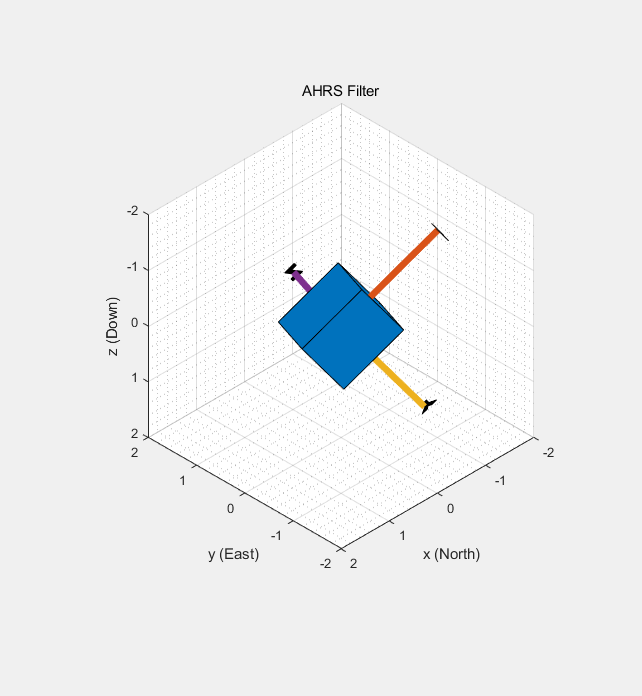

tic;
while(toc < stopTimer)
    data = readline(imu);
    data = str2double(strsplit(data, ','));
    rotators = FUSE(data(2:4),data(5:7),data(8:10));
    for j = numel(rotators)
        viewer(rotators(j));
    end
end

tic;
while(toc < stopTimer)
    data = readline(imu);
    data = str2double(strsplit(data, ','));
    rotators = FUSE(data(2:4),data(5:7),data(8:10));
    for j = numel(rotators)
        viewer(rotators(j));
    end
end

다음 사용 중 오류가 발생함:  () 
입력 인수가 부족합니다. 3개(System Object 외에)여야 하는데 1개를 받았습니다.

viewer = HelperOrientationViewer('Title',{'Ecompass Algorithm'});
stopTimer = 30;

tic;
while(toc < stopTimer)
    data = readline(imu);
    data = str2double(strsplit(data, ','));
    rotators = ecompass(data(2:4), data(8:10));
    for j = numel(rotators)
        viewer(rotators(j));
    end
end

입력 인수가 부족합니다.

오류 발생: ecompass (62번 라인)
if isempty(m) && isempty(a)

tic;
while(toc < stopTimer)
    data = readline(imu);
    data = str2double(strsplit(data, ','));
    rotators = data(5:7);
    for j = numel(rotators)
        viewer(rotators(j));
    end
end

Updating server code on board Uno (COM4). This may take a few minutes.
